 
% if loaded checkpoint.mat
path = strcat( "\\citadel.bio.brandeis.edu\sharespace-commsub\data\", animal)

path = "\\citadel.bio.brandeis.edu\sharespace-commsub\data\JS21"

addpath(path)

path2 = "C:\Users\BrainMaker\MATLAB Drive\Shared"

path2 = "C:\Users\BrainMaker\MATLAB Drive\Shared"

cd(path2)
addpath(genpath('utils')); % all folders in utils added, including semedo code

Figure 2A: Cofiring in source and target

Figure 2B: Prediction Performance

Figure 4A/B: Results from rank regress

Figure 4C: How optimal number of predicitive dimensions compare between hpc and pfc

## Figure 2

#### A: How pairs of neuron in source/target co-fire

cofiringstats = load("cofiring.mat");
all_pairs_across_regions = [];
all_pairs_within_hpc = [];

mean_hpcorr = [];
mean_hhcorr = [];

std_hhcorr = [];
std_hpcorr = [];
for p = 1:Option.numPartition
    for i = 1:nPatterns
        curr_source = X_source{1,1,i}';
        curr_HPC = X_target{1,1,i}';
        curr_PFC = X_target{1,2,i}';
        
        linearized_hh = plots.calculatePatternCofiring(curr_source, curr_HPC);
        linearized_hp = plots.calculatePatternCofiring(curr_source, curr_PFC);
        
        all_pairs_within_hpc = [all_pairs_within_hpc, linearized_hh];
        all_pairs_across_regions = [all_pairs_across_regions, linearized_hp];
    end
    cur_mean_hhcorr = mean(all_pairs_within_hpc(~isnan(all_pairs_within_hpc)));
    cur_std_hhcorr = std(all_pairs_within_hpc(~isnan(all_pairs_within_hpc)));
    
    cur_mean_hpcorr = mean(all_pairs_across_regions(~isnan(all_pairs_across_regions)));
    cur_std_hpcorr = std(all_pairs_across_regions(~isnan(all_pairs_across_regions)));
    
    mean_hhcorr = [mean_hhcorr, cur_mean_hhcorr];
    mean_hpcorr = [mean_hpcorr, cur_mean_hpcorr];
    
    std_hhcorr = [std_hhcorr, cur_mean_hhcorr];
    std_hpcorr = [std_hpcorr, cur_mean_hpcorr];
    
end
figure (500)
subplot(2,1,1)
ax1 = nexttile;
hist_hh = histogram(all_pairs_within_hpc)

hist_hh =   Histogram with properties:

             Data: [1×118080 double]
           Values: [1×110 double]
          NumBins: 110
         BinEdges: [1×111 double]
         BinWidth: 0.0050
        BinLimits: [-0.0500 0.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


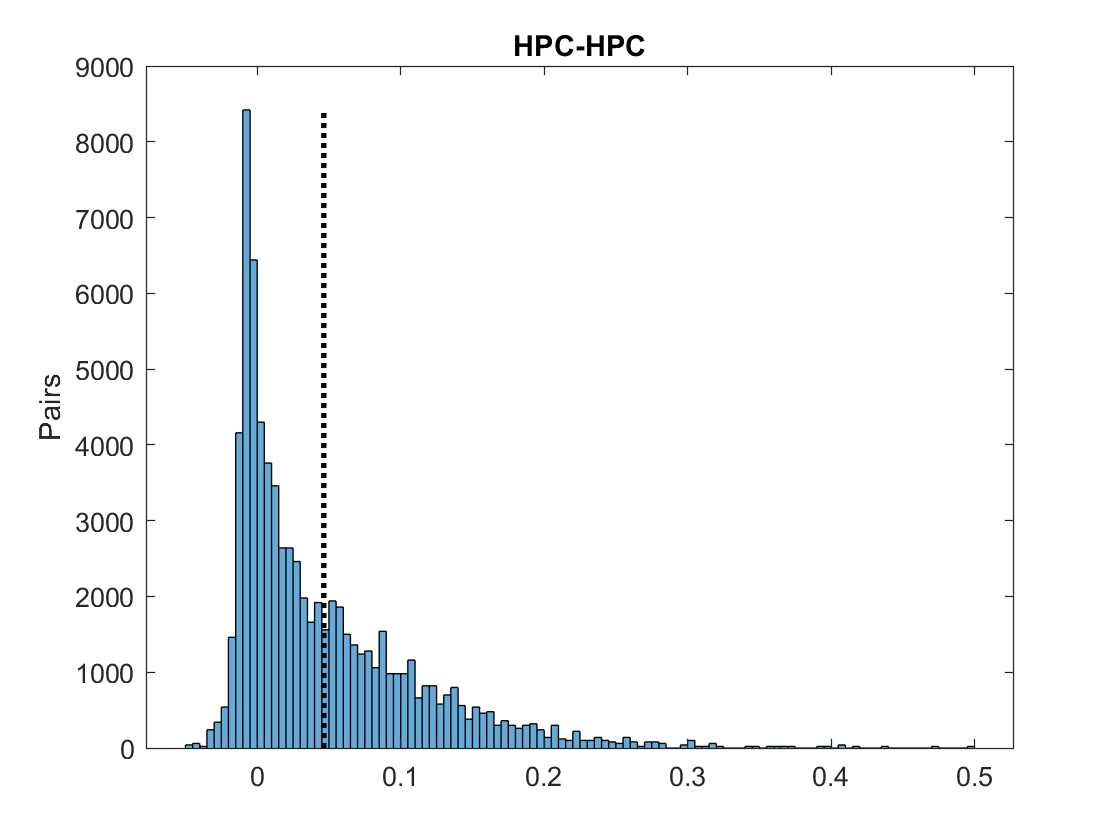

ylabel("Pairs")
title ("HPC-HPC")
example_mean_hhcorr = mean_hhcorr(1);
example_std_hhcorr = std_hhcorr(1);

hold on
lineObject=line([example_mean_hhcorr,example_mean_hhcorr],[0 max(hist_hh.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black

subplot(2,1,2)
ax2 = nexttile;
hist_hp = histogram(all_pairs_across_regions)

hist_hp =   Histogram with properties:

             Data: [1×118080 double]
           Values: [1×128 double]
          NumBins: 128
         BinEdges: [1×129 double]
         BinWidth: 0.0050
        BinLimits: [-0.0500 0.5900]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


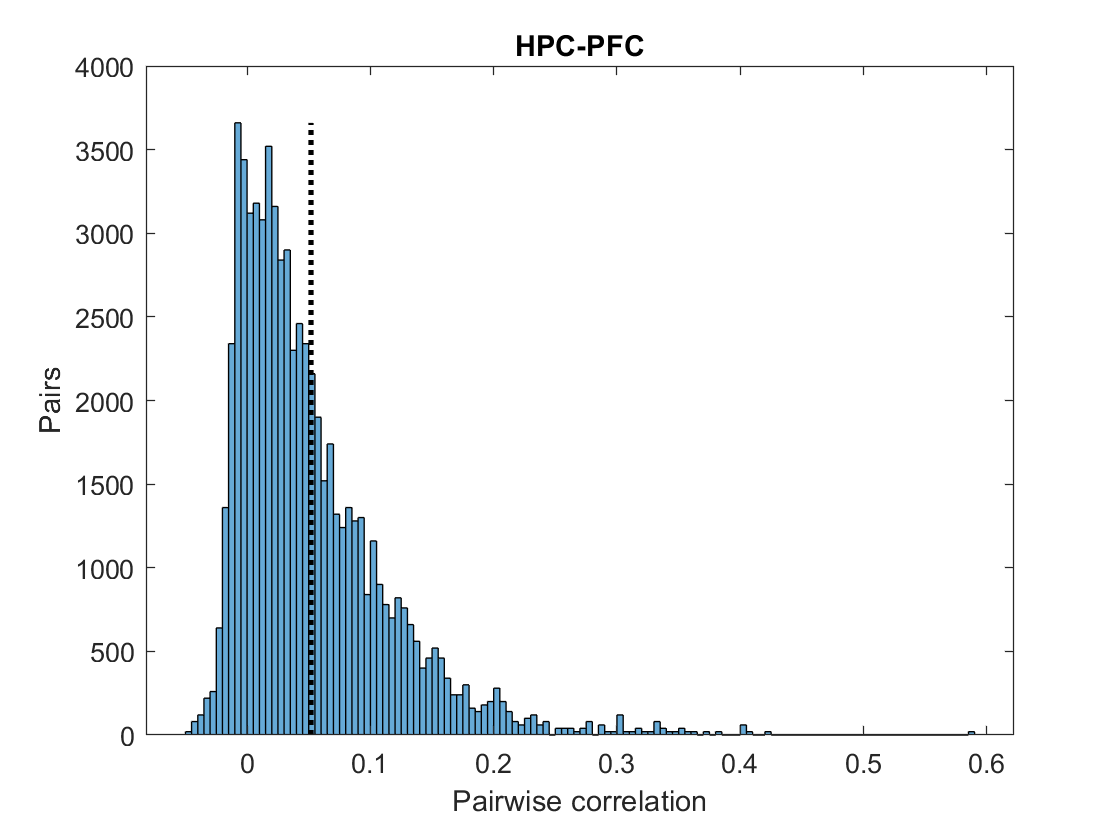

ylabel("Pairs")
title ("HPC-PFC")
example_mean_hpcorr = mean_hpcorr(1);
example_std_hpcorr = std_hpcorr(1);

lineObject=line([example_mean_hpcorr,example_mean_hpcorr],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
xlabel("Pairwise correlation")
linkaxes([ax1,ax2],'x');

[h_corrdiff,p_corrdiff] = kstest2(all_pairs_across_regions,all_pairs_within_hpc);

% saving meaningful stats and the corresponding Option fields in a csv
Optiontable = table(struct2array(Option))

Optiontable = table
        Var1     
    _____________

    [1×10 string]


Resulttable = table(mean(mean_hhcorr), mean(std_hhcorr), mean(mean_hpcorr), mean(std_hpcorr), h_corrdiff, p_corrdiff)

Resulttable = 1×6 table
      Var1        Var2        Var3        Var4      h_corrdiff    p_corrdiff 
    ________    ________    ________    ________    __________    ___________

    0.048022    0.048022    0.035544    0.035544      true        6.1857e-139



% cofiringstats.cofiringRow = [cofiringstats.cofiringRow; table(Optiontable, Resulttable)];
% save('cofiring', 'cofiringstats')


% print stats
formatSpec1 = "%s: %0.3f±%0.3f";

sprintf(formatSpec1,Patterns(1,1).directionality,mean(mean_hhcorr),mean(std_hhcorr))

ans = "hpc-hpc: 0.078±0.088"

sprintf(formatSpec1,Patterns(2,1).directionality,mean(mean_hpcorr),mean(std_hpcorr))

ans = "hpc-pfc: 0.062±0.067"


disp(p_corrdiff)

   7.8893e-09



Average correlation:

HPC-HPC: 0.1413 ± 0.1047

HPC-PFC: 0.0397 ± 0.0509

p < 0.01 for difference between HPC-PFC and HPC-HPC.

*"These weak correlations indicate that only a small fraction of a neuron’s response variability*

*can be explained by another individual neuron"*

#### B: Prediction Performance

predictionstats = load("prediction.mat");
figure(600), clf
% how well a single neuron can predict stuff
all_single_prediction_hh = [];
all_single_prediction_hp = [];

patternPerformance_pfc = []; % prediction of
patternPerformance_hpc = [];

for i = 1:nPatterns
    curr_source = (X_source{i})';
    
    for d = 1:2
        curr_target = (X_target{d,i})';
        for k = 1:nSource
            curr_singleB = Patterns(d,i).rankRegress.singlesource_B{k};
            curr_singlesource = curr_source(:,k);
            [singlepattern,~] = plots.calculatePredictionPerformance(curr_singlesource,curr_target,  curr_singleB);
            if d==1
                [all_single_prediction_hh] = [all_single_prediction_hh singlepattern];
            else
                [all_single_prediction_hp] = [all_single_prediction_hp singlepattern];
            end
        end
    end
end

median_singlehh = median(all_single_prediction_hh(~isnan(all_single_prediction_hh)));
temp = all_single_prediction_hp(~isinf(all_single_prediction_hp));
temp = temp(~isnan(temp));
median_singlehp = median(temp);


r_square_hh = [];
r_square_hp = [];

for i = 1:nPatterns
    curr_source = (X_source{i})';
    curr_targethpc = (X_target{1,i})';
    curr_targetpfc = (X_target{2,i})';
    
    curr_B_hpc = Patterns(1,i).rankRegress.B;
    curr_B_pfc = Patterns(2,i).rankRegress.B;
    
    [patternhpc, meanhpc] = plots.calculatePredictionPerformance(curr_source, curr_targethpc, curr_B_hpc);
    [patternpfc, meanpfc] = plots.calculatePredictionPerformance(curr_source, curr_targetpfc, curr_B_pfc);
    
    r_square_hh = [r_square_hh patternhpc];
    r_square_hp = [r_square_hp patternpfc];
    
    patternPerformance_hpc = [patternPerformance_hpc, meanhpc];
    patternPerformance_pfc = [patternPerformance_pfc, meanpfc];
    
end



mean_hh = mean(r_square_hh(~isinf(r_square_hh)));
std_hh  = std(r_square_hh(~isinf(r_square_hh)));

mean_hp = mean(r_square_hp(~isinf(r_square_hp)));
std_hp = std(r_square_hp(~isinf(r_square_hp)));

subplot(2,1,1)
ax1 = nexttile;
hist_hh = histogram(r_square_hh,25)

hist_hh =   Histogram with properties:

             Data: [1×57 double]
           Values: [7 13 9 5 3 5 1 5 2 1 3 0 0 0 0 0 0 0 0 0 0 2 0 0 1]
          NumBins: 25
         BinEdges: [0 0.0227 0.0454 0.0681 0.0908 0.1135 0.1362 0.1589 0.1816 0.2043 0.2270 0.2497 0.2724 0.2951 0.3178 0.3405 0.3632 0.3859 0.4086 0.4313 0.4540 0.4767 0.4994 0.5221 0.5448 0.5675]
         BinWidth: 0.0227
        BinLimits: [0 0.5675]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


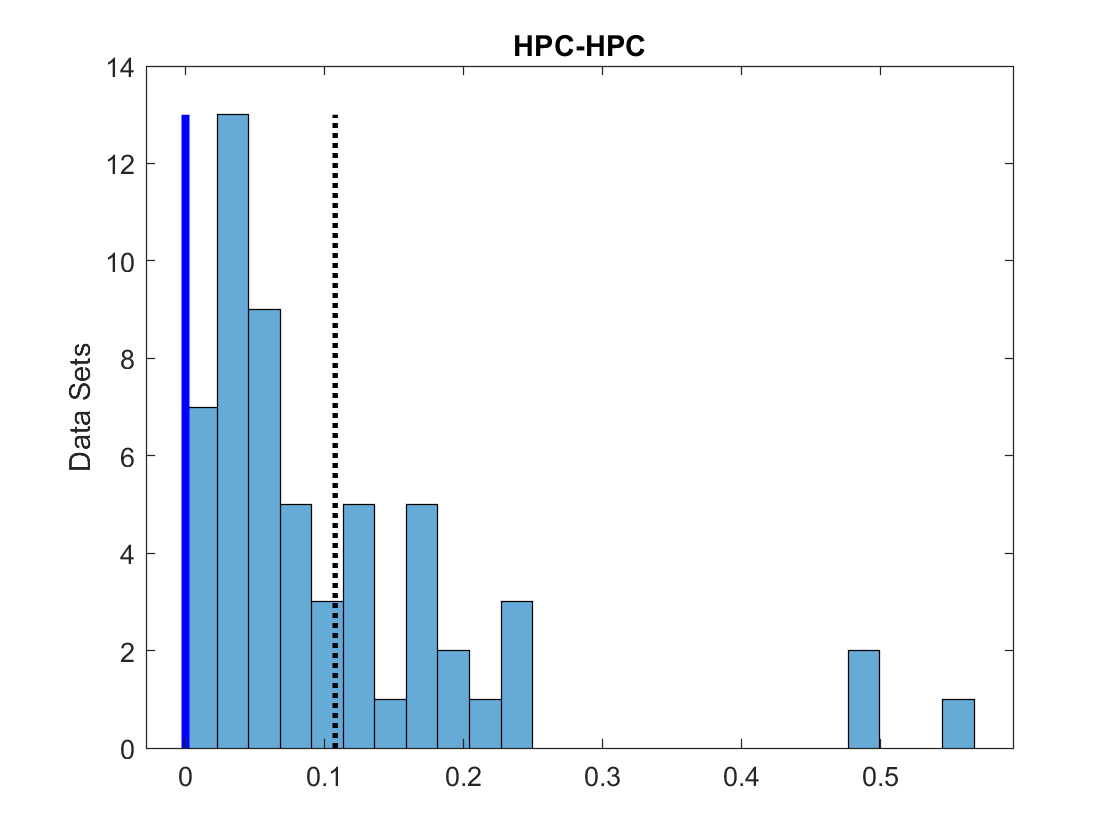

ylabel("Data Sets")
title ("HPC-HPC")
lineObject=line([mean_hh,mean_hh],[0 max(hist_hh.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
if usingSingleprediction
    lineObject2 = line([median_singlehh,median_singlehh],[0 max(hist_hh.Values)]);
    lineObject2.LineWidth = 3;
    lineObject2.Color = 'blue';
end


subplot(2,1,2)
ax2 = nexttile;
hist_hp = histogram(r_square_hp,25)

hist_hp =   Histogram with properties:

             Data: [1×114 double]
           Values: [17 14 9 13 13 6 2 4 5 3 2 3 3 2 0 0 2 5 2 2 3 0 2 0 2]
          NumBins: 25
         BinEdges: [0 0.0117 0.0234 0.0351 0.0468 0.0585 0.0702 0.0819 0.0936 0.1053 0.1170 0.1287 0.1404 0.1521 0.1638 0.1755 0.1872 0.1989 0.2106 0.2223 0.2340 0.2457 0.2574 0.2691 0.2808 0.2925]
         BinWidth: 0.0117
        BinLimits: [0 0.2925]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


% prediction performance from hpc to pfc cells
ylabel("Data Sets")
title ("HPC-PFC")
xlabel("Performance")
linkaxes([ax1,ax2],'x');

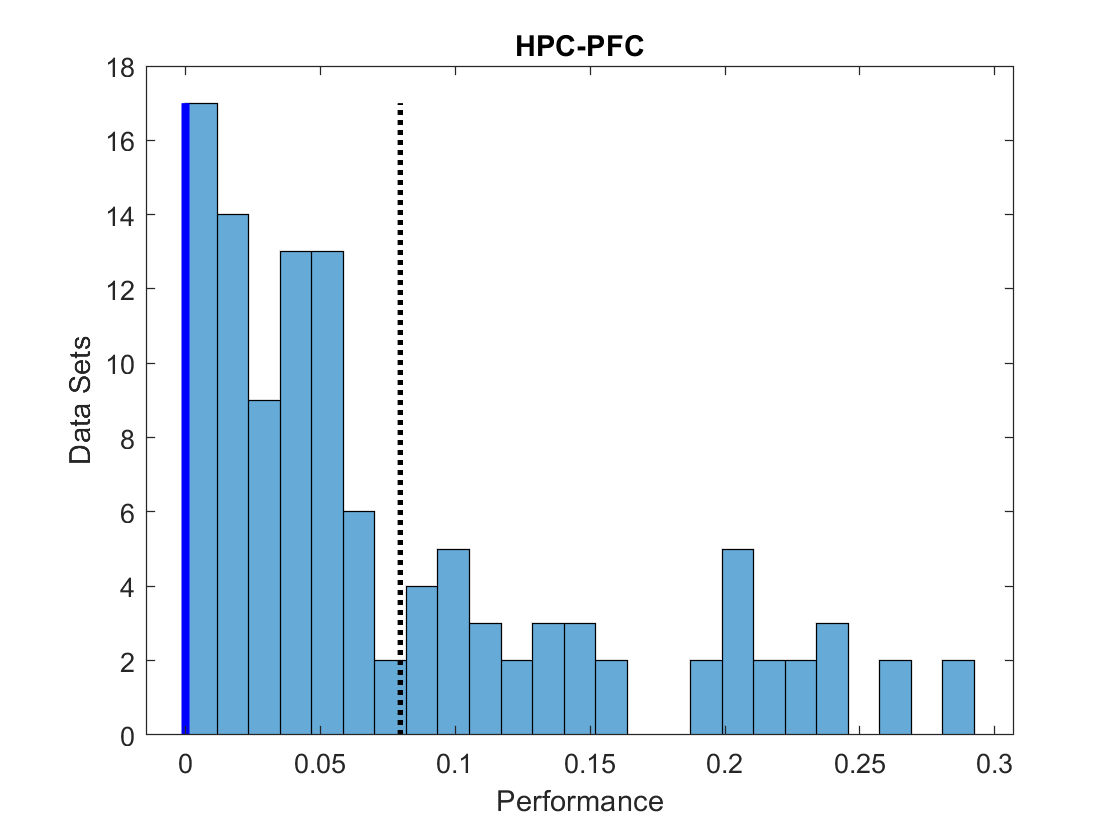

lineObject=line([mean_hp,mean_hp],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
if usingSingleprediction
    lineObject2 = line([median_singlehp,median_singlehp],[0 max(hist_hp.Values)]);
    lineObject2.LineWidth = 3;  % Thicken the line
    lineObject2.Color = 'blue'; % Color it black
end

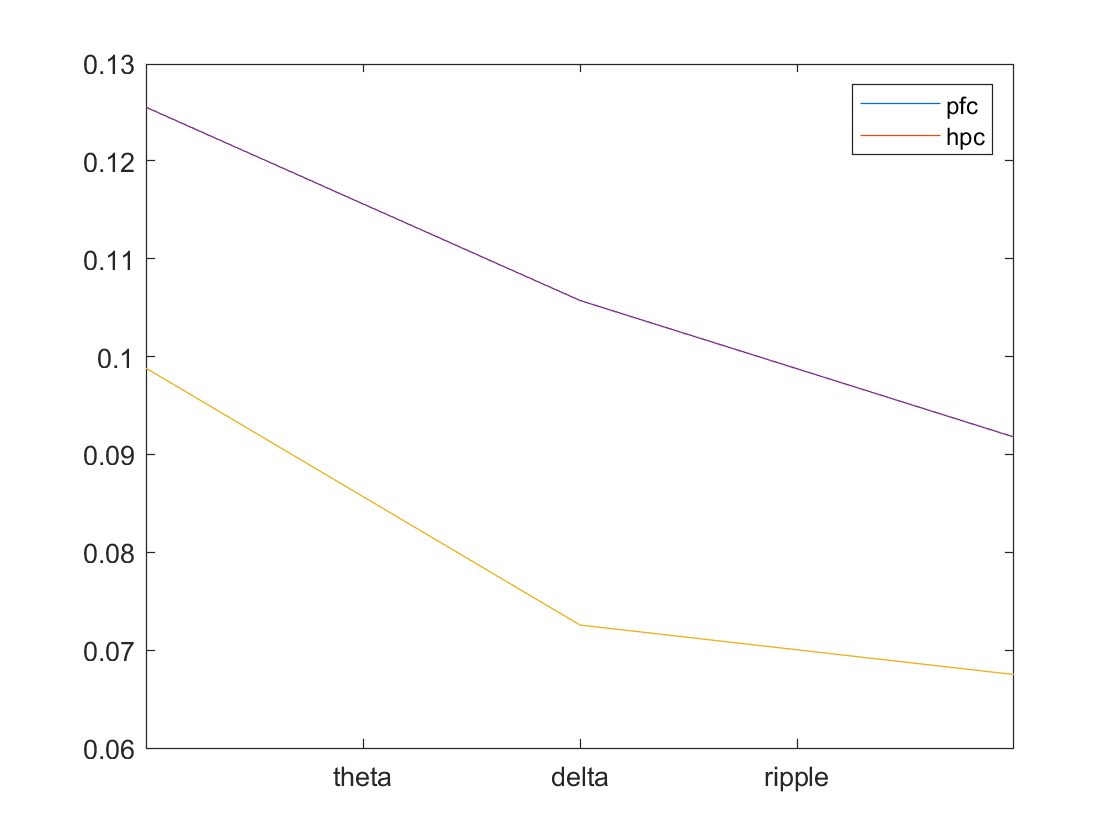

figure(601)
plot(patternPerformance_pfc);
hold on
plot(patternPerformance_hpc);

xticks([1.5, 2, 2.5])
xticklabels({'theta','delta','ripple'})
legend("pfc","hpc")


% saving meaningful stats and the corresponding Option fields in a csv
Predictiontable  = table(mean_hh, std_hh, mean_hp, std_hp)

Predictiontable = 1×4 table
    mean_hh    std_hh     mean_hp      std_hp 
    _______    _______    ________    ________

    0.10766    0.11585    0.079629    0.076522


predictionstats.predictionRow = [predictionstats.predictionRow; table(Optiontable, Predictiontable )];

An error occurred when concatenating the table variable 'Optiontable' using VERTCAT.

Caused by:
    Error using tabular/vertcat (line 178)
    An error occurred when concatenating the table variable 'Var1' using VERTCAT.
        Error using vertcat
        Dimensions of arrays being concatenated are not consistent.

save('prediction','predictionstats');


% print stats
formatSpec1 = "%s: %0.3f±%0.3f";
disp("Prediction Performance on Average")
sprintf(formatSpec1,Patterns(1,1).directionality,mean_hh,std_hh)
sprintf(formatSpec1,Patterns(2,1).directionality,mean_hp,std_hp)
if usingSingleprediction
    disp('single source prediction median')
    formatSpec2 = "%s: %0.5e";
    sprintf(formatSpec2,Patterns(1,1).directionality,median_singlehh)
    sprintf(formatSpec2,Patterns(1,2).directionality,median_singlehp)
    
end


## Figure 4

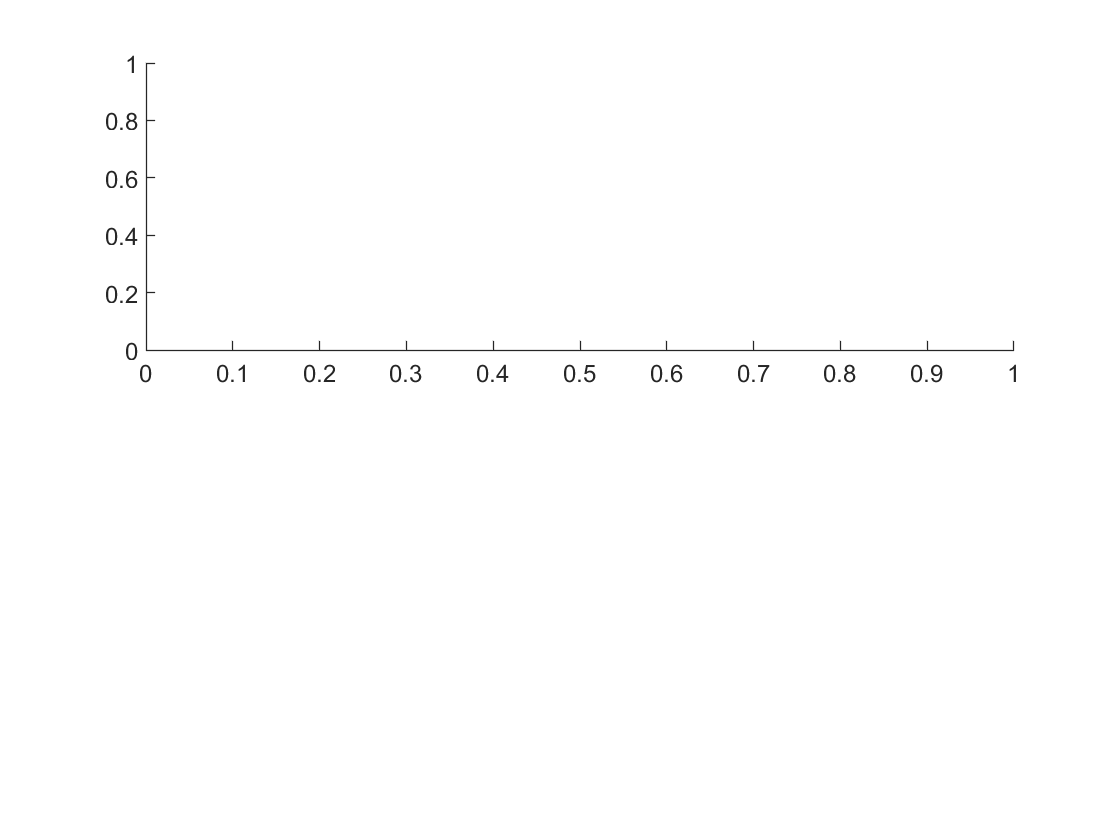

Error using errorbar>checkSingleInput (line 270)
XData must be the same size as YData.

Error in errorbar (line 94)
x = checkSingleInput(x, sz, 'XData');

Error in plots.plotPr

x_hp = 1:nPFCneurons;
x_hh = 1:nHPCneurons-nSource;
for i = 1:nPatterns
    figure(700+i)
    
    for j = 1:2
        subplot(2,1,j)
        curr_cvLoss = Patterns(j,i).rankRegress.cvLoss;
        if j==2
            plots.plotPredictiveDimensions(x_hp,curr_cvLoss);
        else
            plots.plotPredictiveDimensions(x_hh, curr_cvLoss);
        end
        title([Patterns(j,i).name Patterns(j,i).directionality])
        xlim([0,10.5])
        
        hold on
        full_model = 1-curr_cvLoss(1,end);
        plot(1, full_model,'b*');
        text(0.5, full_model+0.01, "Full model")
        
    end
    hold on
    ylim([0 0.3])
end

#### 4C

#### How optimal number of predicitive dimensions compare between hpc and pfc (this is gathered over animals)

dimensions_hpc = [];
dimensions_pfc = [];
% for animal in animal tables, retrieve those with same option conditions,
% and do the following

% collect respective dim_pfc and dim_hpc for each pattern, and divide to
% get the ratio.

figure(800)
ylabel("PFC Predictive Dimensions")
xlabel("Target HPC Predictive Dimensions")

for i = 1:nPatterns
    
    
end